# Analise das distribuições no disco rotor

### descida com velocidade de avanço

clc
clear
close all

mass_payload = 20;

vehicle_position = [0; 0; 0];
vehicle_velocity = [80; 0; -20];
vehicle_orientation = [0; 0; 0];

Nb = 2;
Span = 1;
RootBladeDistance = 0.1;
theta = -10;
twist_rate = 0;
chord = 0.17;

induced_velocity = 0;

RPM = 1500;

azimutal_points = 600;
No_elements = 200;

blade_integrator = 'Trapezoidal'; % 'Boole'; 'Rectangle'; 'Simpson';

sim_init_rotor_simulation
[F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE)

F_rotor = 1.0e+03 *

   -0.0000
   -0.0000
    1.0580


T_rotor =    -0.0000
    0.0000
  -49.8800


rotor_distribution_data =   RotorAzimutalDistribution with properties:

    blade_distribution_data: [1×500 BladeDistribution]
          azimutal_position: [500×1 double]


azimutal_points_to_plot = [90 180 360];
colors = {'b', 'k', 'r', 'm'}; % Azul, preto, vermelho, roxo

#### Velocidade Tangencial

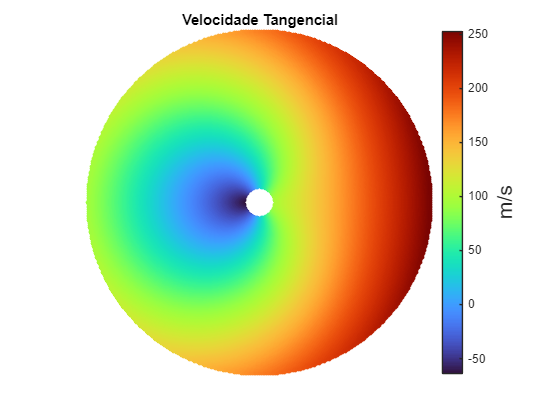

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_T;
end
polarPlot(azimutes, rho, values, "Velocidade Tangencial", "m/s", "./studies/rotor_analysis/sim_D/U_T.eps")

#### Velocidade Radial

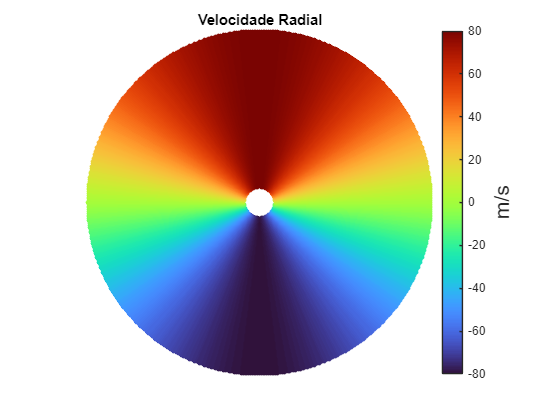

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_R;
end
polarPlot(azimutes, rho, values, "Velocidade Radial", "m/s", "./studies/rotor_analysis/sim_D/U_R.eps")

#### Velocidade Vertical

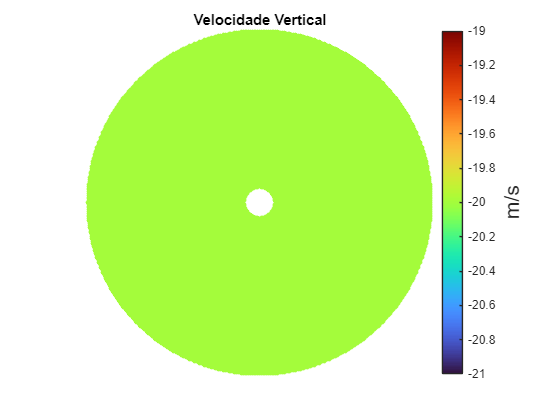

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_P;
end
polarPlot(azimutes, rho, values, "Velocidade Vertical", "m/s", "./studies/rotor_analysis/sim_D/U_P.eps")

#### Modo de escoamento

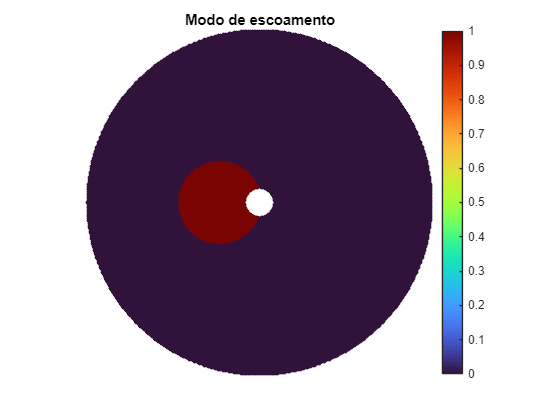

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).flow_mode;
end
polarPlot(azimutes, rho, values, "Modo de escoamento", "", "./studies/rotor_analysis/sim_D/flow_mode.eps")

#### Número de Reynolds

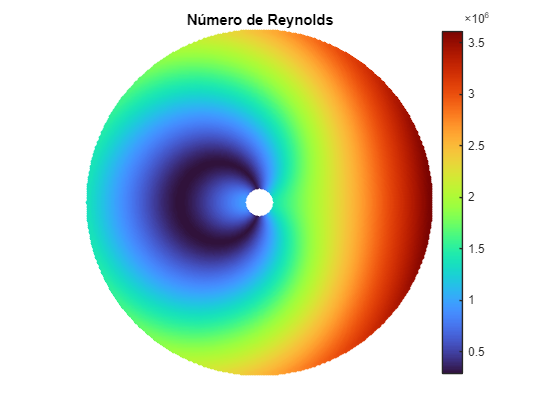

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Re;
end
polarPlot(azimutes, rho, values, "Número de Reynolds", "", "./studies/rotor_analysis/sim_D/Re.eps")

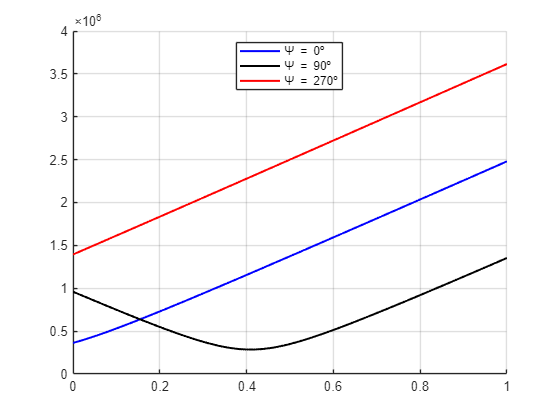

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).Re;

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Número de Mach

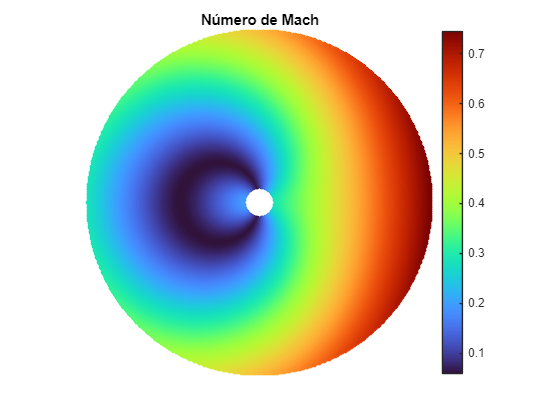

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Ma;
end
polarPlot(azimutes, rho, values, "Número de Mach", "", "./studies/rotor_analysis/sim_D/mach.eps")

#### Ângulo de picada

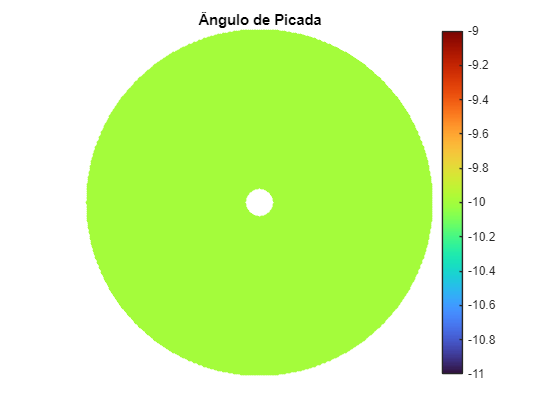

for i=1:length(azimutes)
    values(i, :) = BLADE.theta;
end
polarPlot(azimutes, rho, values, "Ângulo de Picada", "", "./studies/rotor_analysis/sim_D/theta.eps")

#### Ângulo de incidência

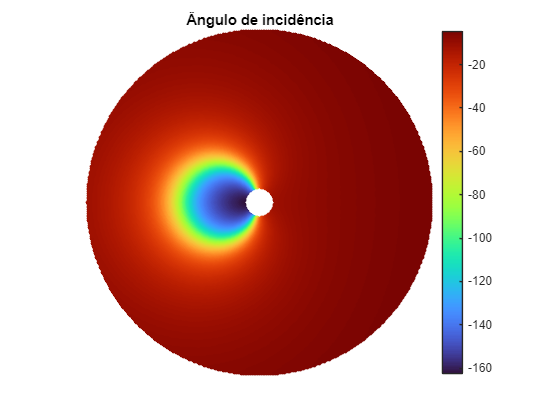

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).phi;
end
polarPlot(azimutes, rho, values, "Ângulo de incidência", "", "./studies/rotor_analysis/sim_D/phi.eps")

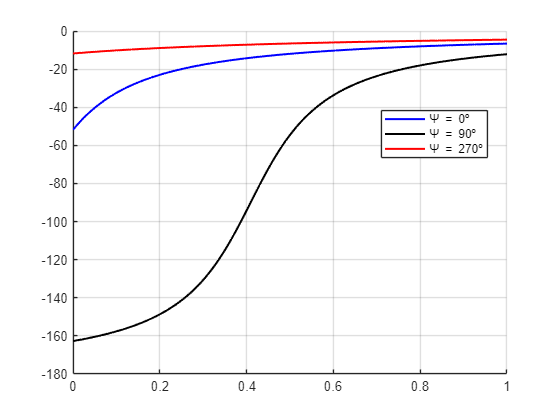

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).phi;

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Ângulo de ataque

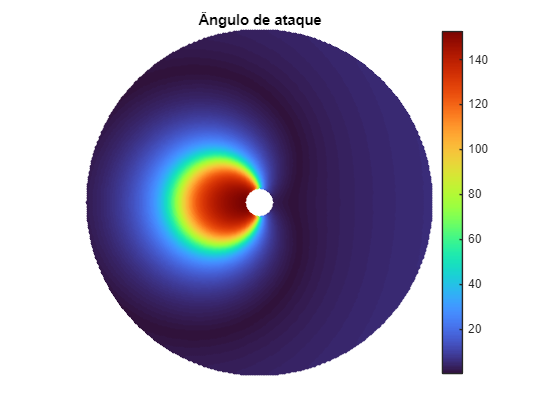

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).alpha;
end
polarPlot(azimutes, rho, values, "Ângulo de ataque", "", "./studies/rotor_analysis/sim_D/alpha.eps")

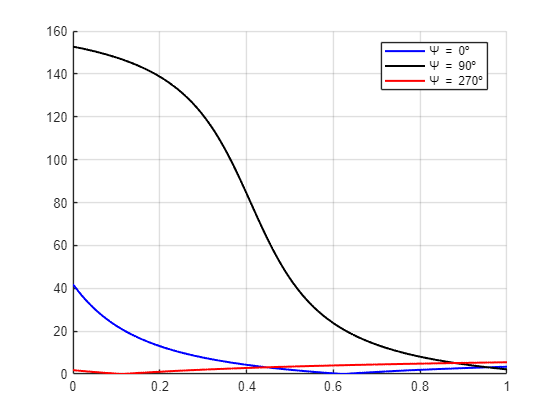

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).alpha;

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Coeficiente de Sustentação

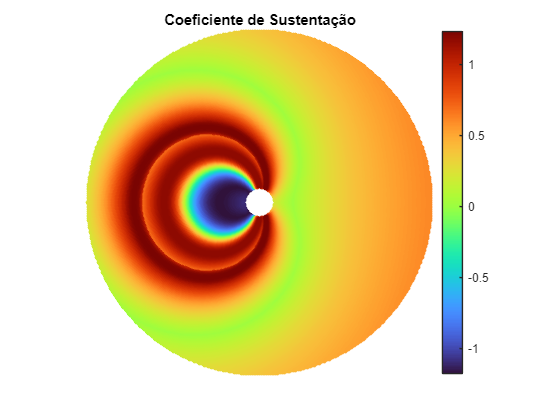

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cl;
end
polarPlot(azimutes, rho, values, "Coeficiente de Sustentação", "", "./studies/rotor_analysis/sim_D/cl.eps")

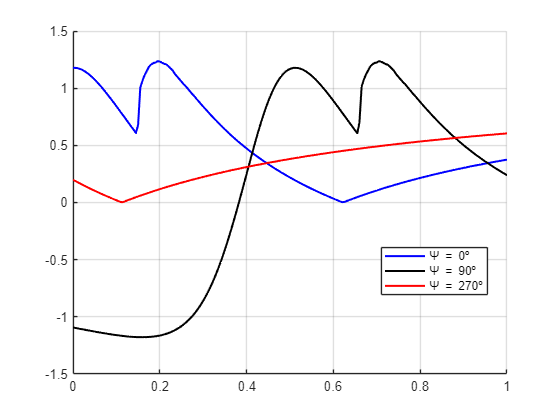

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).Cl;

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Coeficiente de Arrasto

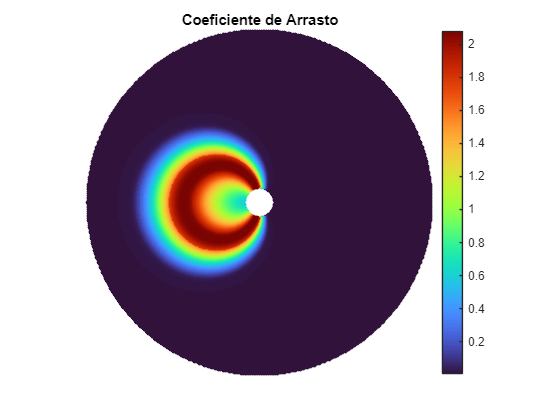

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cd;
end
polarPlot(azimutes, rho, values, "Coeficiente de Arrasto", "", "./studies/rotor_analysis/sim_D/cd.eps")

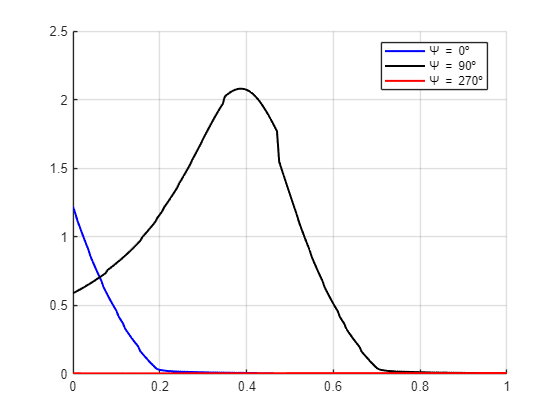

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).Cd;

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Força em X - referencial do aerodinâmico

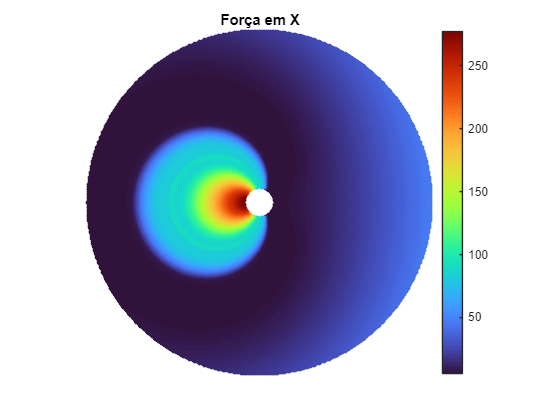

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(1, :);
end
polarPlot(azimutes, rho, values, "Força em X", "","./studies/rotor_analysis/sim_D/dFx_a.eps")

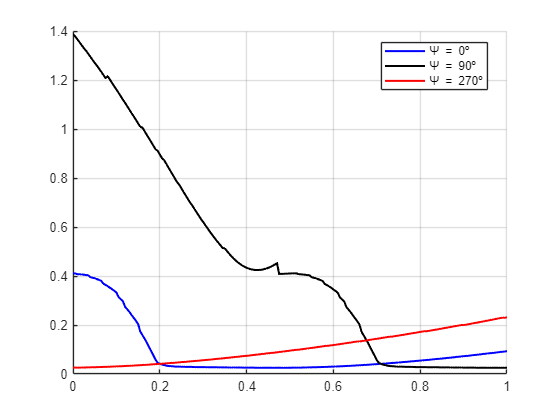

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).dF_a(1, :);

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v*BLADE.dy, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Força em Y - referencial do aerodinâmico

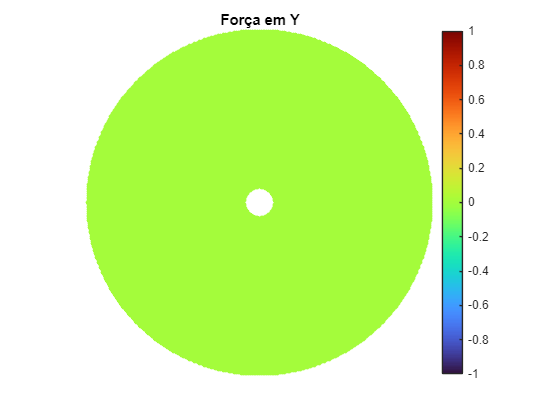

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(2, :);
end
polarPlot(azimutes, rho, values, "Força em Y", "", "./studies/rotor_analysis/sim_D/dFy_a.eps")

#### Força em Z - referencial do aerodinâmico

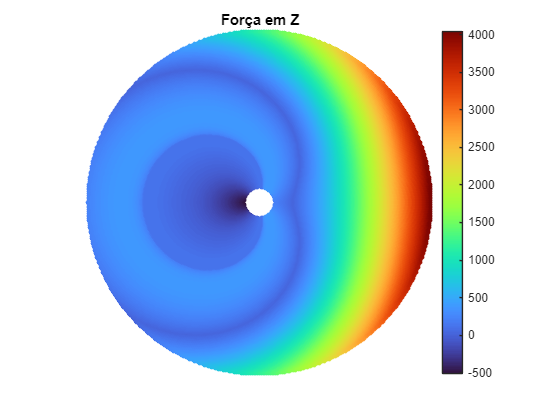

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(3, :);
end
polarPlot(azimutes, rho, values, "Força em Z", "", "./studies/rotor_analysis/sim_D/dFz_a.eps")

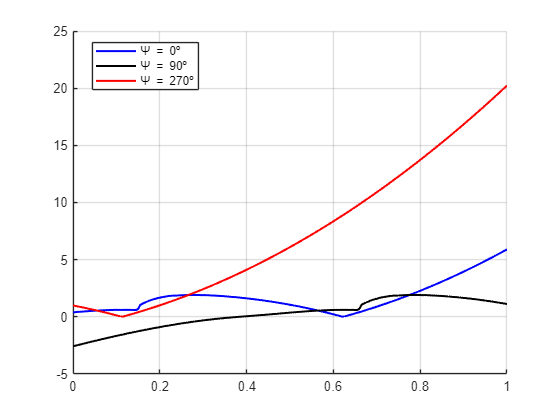

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).dF_a(3, :);

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v*BLADE.dy, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Força em X - referencial do rotor

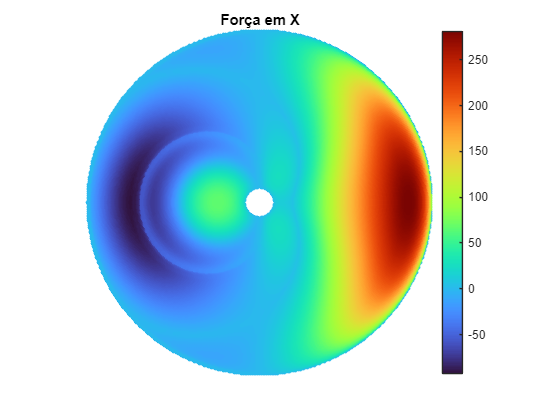

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(1, :);
end
polarPlot(azimutes, rho, values, "Força em X", "", "./studies/rotor_analysis/sim_D/dFx_r.eps")

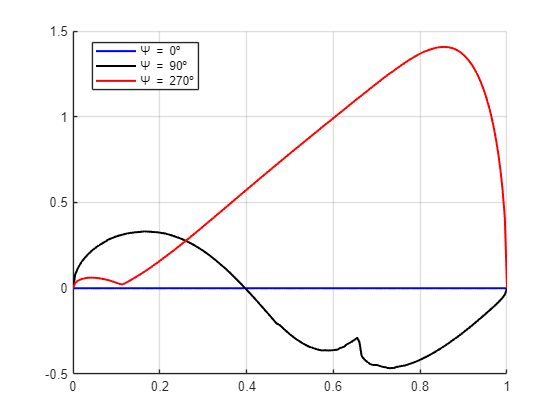

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).dF_r(1, :);

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v*BLADE.dy, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Força em Y - referencial do rotor

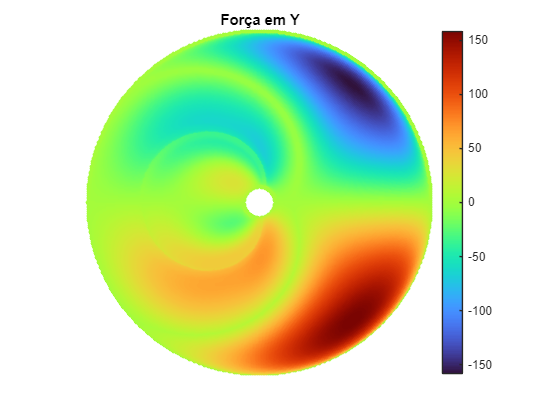

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(2, :);
end
polarPlot(azimutes, rho, values, "Força em Y", "", "./studies/rotor_analysis/sim_D/dFy_r.eps")

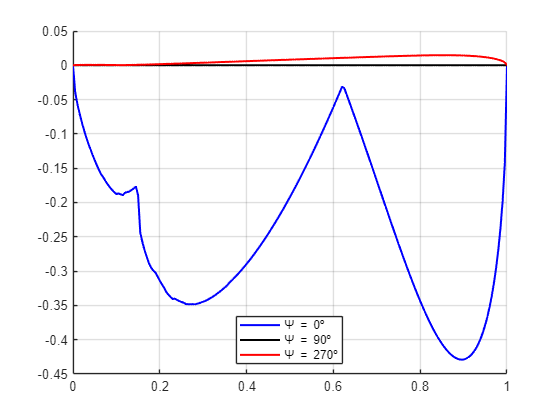

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).dF_r(2, :);

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v*BLADE.dy, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on

#### Força em Z - referencial do rotor

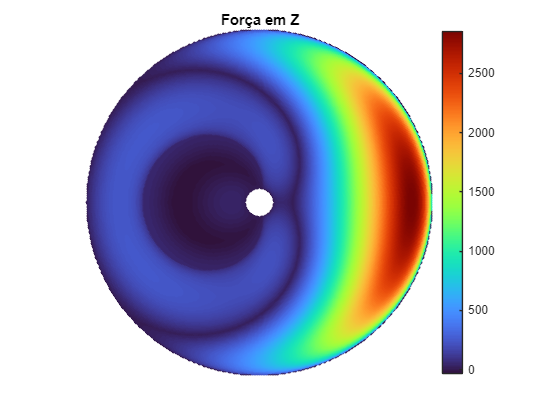

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(3, :);
end
polarPlot(azimutes, rho, values, "Força em Z", "", "./studies/rotor_analysis/sim_D/dFz_r.eps")

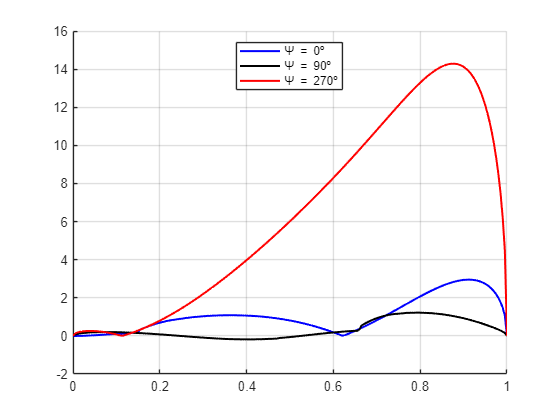

figure()
hold on;
for i = 1:length(azimutal_points_to_plot)
    [~, index] = min(abs(rotor_distribution_data.azimutal_position - azimutal_points_to_plot(i)));
    v = rotor_distribution_data.blade_distribution_data(index).dF_r(3, :);

    s = ['\Psi = ' num2str(azimutal_points_to_plot(i) - 90) 'º'];

    plot((rho - BLADE.RootBladeDistance)/BLADE.Span , v*BLADE.dy, 'LineWidth', 1.5, 'DisplayName', s, 'Color', colors{i})
end
hold off
legend("Location", "best")
grid on